# 最短路径

graph：生成无向图

digraph：生成有向图

G = graph(A)：使用邻接矩阵A创建无向图G，A中的元素值代表边的权重

G = graph(s,t,weights)：使用顶点对组（两个矩阵）s，t和权重向量

# 设备更新问题

根据题目，已写出邻接矩阵：


$$W=\left[\begin{array}{cccccc}
0 & 15 & 20 & 27 & 37 & 54 \\
\infty & 0 & 15 & 20 & 27 & 37 \\
\infty & \infty & 0 & 16 & 21 & 28 \\
\infty & \infty & \infty & 0 & 16 & 21 \\
\infty & \infty & \infty & \infty & 0 & 17 \\
\infty & \infty & \infty & \infty & \infty & 0
\end{array}\right]$$


**注意：MATLAB中，不存在的边（即邻接矩阵中正无穷）的权重写作0**

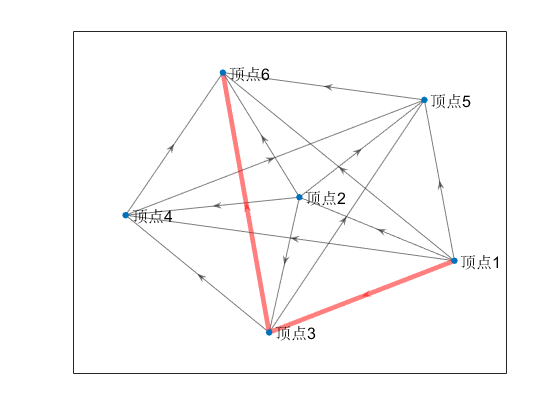

% 写出邻接矩阵，先定义全是0的矩阵，再修改不是0的元素
a = zeros(6);
a(1,[2:6])= [15 20 27 37 54];
a(2,[3:6]) = [15 20 27 37];
a(3,[4:6]) = [16 21 28];
a(4,[5:6]) = [16 21];
a(5,6) = 17;

% 给每个顶点标注名称，放在元胞s里（该部分不重要，不感兴趣可跳过）
% int2str([1:6]')将整数1到6六个数转化为字符
% strcat把字符串水平串联起来
% strcat('v',int2str([1:6]'))把v和字符1到6拼起来，
% 得到6行的数组，分别有v1，v2等
% 为何其中行向量[1:6]要转置成列向量？如果用行向量，则得到的是一行"v1 2 3 4 5 6"

s = cellstr(strcat('顶点',int2str([1:6]')));
G = digraph(a,s);   % 不加s不影响求解
% plot绘图有很多参数可以设置，使图尽量美观
P = plot(G,'layout','force','EdgeColor','k','NodeFontSize',12);

[path,d] = shortestpath(G,1,6);

% 在图片P中，设置求得的最短路径path的属性（颜色、粗细等等）
highlight(P,path,"EdgeColor","red",'LineWidth',3.5)

更改的图论的图布局，设置‘layout’。本代码中设置'layout','force'，是实现在相邻节点之间使用引力，在远距离节点之间使用斥力。

[https://ww2.mathworks.cn/help/matlab/ref/matlab.graphics.chart.primitive.graphplot.layout.html?s_tid=doc_ta](https://ww2.mathworks.cn/help/matlab/ref/matlab.graphics.chart.primitive.graphplot.layout.html?s_tid=doc_ta)

求解得到的path=[1,3,6]意味着顶点1到顶点6的最短路径为1到3再到6；

d = 48意味着最短路径长度为48；

%本文件出自b站/公众号：数学建模BOOM
% 关注公众号：数学建模BOOM，回复"购买"
% 获取全套视频课程+配套PPT课件+代码文件+完善售后服务+后续课程更新
% 版权所有，侵权必究。本文件仅供购买者学习使用，不得随意传播，否则为侵权行为
